clear;
load result_MLR.mat;
load YTests.mat;



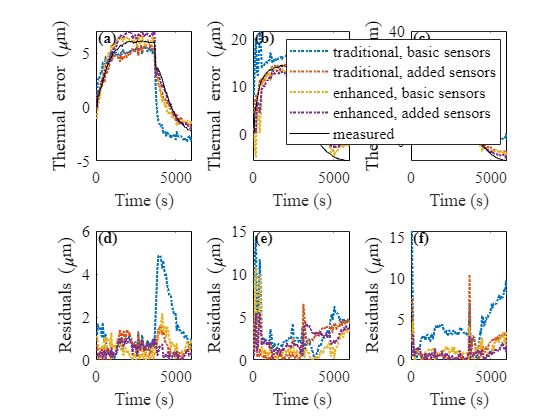

%几种常用的RGB格式的颜色，可选择使用
figure;
color=[0,0.447,0.741;
       0.850,0.325,0.098;
       0.929,0.694,0.125;
       0.494,0.184,0.556;
       0.466,0.674,0.188;
       0.301,0.745,0.933;
       0.635,0.078,0.184];
sRange=[900,3600,3720;
    900,3000,3120;
    900,3600,3720];
MaxE=zeros(3,4);
for sub=1:3
    subplot(2,3,sub);
    t=60:60:6000;
    for i=1:4
        plot(t,YTest_Preds{i}{sub},':','Color',color(i,:),'LineWidth',1.5);
        hold on;
    end
    plot(t,outputs{sub},'k');
    xlabel("Time (s)");
    ylabel("Thermal error (\mum)");

    yyaxis right;
    ylim([0,2]);
    text(100,1.9,"("+ char(96+sub)+")",'fontsize',12,'fontname','times new roman','FontWeight','bold');
    set(gca,'fontsize',12,'fontname','times new roman',"YColor",[0,0,0],"YTick",[]);

    if sub==3
        legend(["traditional, basic sensors","traditional, added sensors","enhanced, basic sensors","enhanced, added sensors","measured"],'fontsize',12);
    end    
    subplot(2,3,3+sub);
    for i=1:4
        res=abs(YTest_Preds{i}{sub}-outputs{sub});
        plot(t,res,':','Color',color(i,:),'LineWidth',1.5);
        hold on;
        max1=res(sRange(sub,1)/60:sRange(sub,2)/60);
        max2=res(sRange(sub,3)/60:end);
        MaxE(sub,i)=max([max1,max2]);
    end
    xlabel("Time (s)");
    ylabel("Residuals (\mum)");

    yyaxis right;
    ylim([0,2]);
    text(100,1.9,"("+ char(96+sub+3)+")",'fontsize',12,'fontname','times new roman','FontWeight','bold');
    set(gca,'fontsize',12,'fontname','times new roman',"YColor",[0,0,0],"YTick",[]);
end

max(MaxE)

ans =     9.5987    6.4464    3.5998    4.3227


mean([RMSEs{5,:}])

ans =     3.5380    1.7871    1.5345    1.3877
